## Problem Distance Protection 4: Fault resistance

Consider the 345 kV transmission line as  with double infeed as shown below.

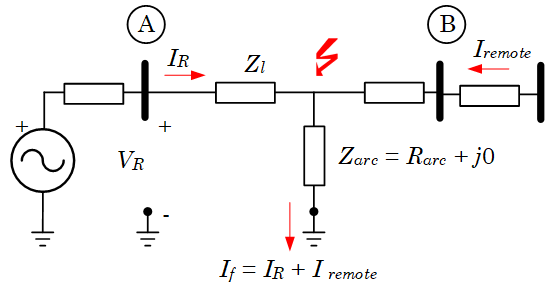

The line impedance to the fault point be *Z**l* = (5+*j*50) Ohms, while the short fault resistance is *R**arc*= 7.5 ohms.

During thefault, currentin the line is:

*I**R*= (400 ∠-85°)A 

The contribution current during the fault is:

*I**remote*= (600 ∠-90°)A 

Determine the apparent impedance (*Z**app*) seen by the relay.  

Created by: Professor Francisco Gonzalez-Longatt, March 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

#GitHub: [https://github.com/fglongatt/PowerSystemProtections](https://github.com/fglongatt/PowerSystemProtections) 

#ResearchGate: [https://www.researchgate.net/project/Power-System-Protection-13](https://www.researchgate.net/project/Power-System-Protection-13) 

#### SOLUTION

clc
clear all

The line impedance to the fault point be

Zl = 5 + 50 * i;    % Positive sequence impedance in Ohms
Vll = 345;  % Vll: Rated voltage in kV
Rarc = 7.5; % Rarc: Arc resistance in Ohms

The remote and local contribution to the fault:

Iremote = 725 * exp(-90*i*pi/180);
IR = 320 * exp(-87*i*pi/180);

The apparent (*Z**app*) impedance that sees the relay results:

Zapp = Zl + Rarc*( 1 + Iremote/IR)

Zapp = 29.4689 + 49.1107i

fprintf(' Zapp = (%5.5f ∠ %5.5f°) Ω', abs(Zapp), angle(Zapp)*180/pi)

 Zapp = (57.27370 ∠ 59.03411°) Ω

fprintf(' Zapp = (%5.5f + j%5.5f) Ω ', real(Zapp),imag(Zapp))

 Zapp = (29.46890 + j49.11070) Ω 